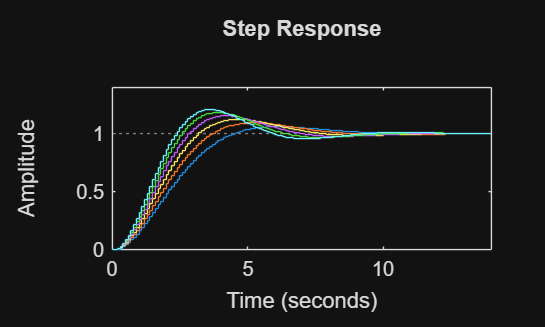

Te = 0.1;
t = [0:1:15];
Gpf = tf(1, [1 30 200 0]);

for K = 5:1:10
    Gr = tf([K 20*K],[1 1]);
    
    Gd = series(Gr, Gpf);
    Gdd = c2d(Gd, Te, 'tustin');
    G0 = feedback(Gdd, 1);
    dstep(G0, t)
    hold on
end